# **絶対音感テストの作成**

## 演習１. 370 Hz (F#4) から740 Hz (F#5) の平均律音を、for 文を用いて低い音から高い音まで半音ずつ順番に再生せよ（合計13音）。それぞれの音は、500ミリ秒の長さと50ミリ秒のRise & Decay Timeを持つ純音とする。尚、sound 関数で音を再生したら、pauseを用いて一時停止すること。

% Sound Settings
Fs = 48000 ; % Sampling Frequency
d = 0.5 ; % Tone duration in second
a = 1 ; % Tone amplitude (from 0.0 to 1.0)
rfd = 0.05 ; % Rise & fall duration in second
Fref = 440 ; % Reference Frequency
SemTs = (-3:+1:+9)' ; % Semitone

% loop for each trial
for i = 1:13
    % current semitone
    semitone = SemTs(i) ;
    % calculate frequency from the semitone
    f = calcS2F(Fref,semitone) ;
    % create current tone
    S = createTone(a,f,d,rfd,Fs) ;
    % play sound & pause
    sound(S,Fs);
    pause
end

## 演習２. 上記の13音をリピートして、合計26音再生せよ。

% Sound Settings
Fs = 48000 ; % Sampling Frequency
d = 0.5 ; % Tone duration in second
a = 1 ; % Tone amplitude (from 0.0 to 1.0)
rfd = 0.05 ; % Rise & fall duration in second
Fref = 440 ; % Reference Frequency
SemTs = (-3:+1:+9)' ; % Semitone 
% Number of repetition
nRepeat = 2 ;
% repeated Semitones to Use
repSemTs = repmat(SemTs,nRepeat,1) ;
% number of trials
nTrial = length(repSemTs) ;

% loop for each trial
for i = 1:nTrial
    % current semitone
    semitone = repSemTs(i) ;
    % calculate frequency from the semitone
    f = calcS2F(Fref,semitone);
    % create current tone
    S = createTone(a,f,d,rfd,Fs) ;
    % play sound & pause
    sound(S,Fs);
    pause
end

## 演習３. randperm 関数を用いて、上記の26音をランダム順で再生せよ。

% Sound Settings
Fs = 48000 ; % Sampling Frequency
d = 0.5 ; % Tone duration in second
a = 1 ; % Tone amplitude (from 0.0 to 1.0)
rfd = 0.05 ; % Rise & fall duration in second
Fref = 440 ; % Reference Frequency
SemTs = (-3:+1:+9)' ; % Semitone 
% Number of repetition
nRepeat = 2 ;
% repeated Semitones to Use
repSemTs = repmat(SemTs,nRepeat,1) ;
% number of trials
nTrial = length(repSemTs) ;
% randomize trial order
iRand = randperm(nTrial) ;
expSemTs = repSemTs(iRand) ;

% loop for each trial
for i = 1:nTrial
    % current semitone
    semitone = expSemTs(i) ;
    % calculate frequency from the semitone
    f = calcS2F(Fref,semitone);
    % create current tone
    S = createTone(a,f,d,rfd,Fs) ;
    % play sound & pause
    sound(S,Fs);
    pause
end

## 演習４. どの音を再生したか、音名を表示せよ。また、各ループについて、Trial 数をテキスト表示せよ。

% Sound Settings
Fs = 48000 ; % Sampling Frequency
d = 0.5 ; % Tone duration in second
a = 1 ; % Tone amplitude (from 0.0 to 1.0)
rfd = 0.05 ; % Rise & fall duration in second
Fref = 440 ; % Reference Frequency
SemTs = (-3:+1:+9)' ; % Semitone 
StrTs = {'F#';'G';'G#';'A';'A#';'B';'C';'C#';'D';'D#';'E';'F';'F#'}; % String
% Number of repetition
nRepeat = 2 ;
% repeated Semitones to Use
repSemTs = repmat(SemTs,nRepeat,1) ;
repStrTs = repmat(StrTs,nRepeat,1) ; 
% number of trials
nTrial = length(repSemTs) ;
% randomize trial order
iRand = randperm(nTrial) ;
expSemTs = repSemTs(iRand) ;
expStrTs = repStrTs(iRand) ;

% loop for each trial
for i = 1:nTrial
    % current semitone
    semitone = expSemTs(i) ;
    % calculate frequency from the semitone
    f = calcS2F(Fref,semitone);
    % create current tone
    S = createTone(a,f,d,rfd,Fs) ;
    % play sound 
    sound(S,Fs);
    % display tone name
    Str = ['Trial ',num2str(i),'/',num2str(nTrial),', ',expStrTs{i},' was played.'];
    disp(Str);
    pause
    pause
    
end

Trial 1/26, G# was played.
Trial 2/26, G# was played.
Trial 3/26, A was played.
Trial 4/26, G was played.
Trial 5/26, F was played.
Trial 6/26, C# was played.
Trial 7/26, D was played.
Trial 8/26, F# was played.
Trial 9/26, C was played.
Trial 10/26, D# was played.
Trial 11/26, A# was played.
Trial 12/26, B was played.
Trial 13/26, E was played.
Trial 14/26, A was played.
Trial 15/26, E was played.
Trial 16/26, G was played.
Trial 17/26, C was played.
Trial 18/26, F# was played.
Trial 19/26, F was played.
Trial 20/26, D was played.
Trial 21/26, C# was played.
Trial 22/26, B was played.
Trial 23/26, F# was played.
Trial 24/26, D# was played.
Trial 25/26, F# was played.
Trial 26/26, A# was played.


## 演習５. 各音を再生した後に、音名を数値入力するよう要求してユーザー入力を取得せよ。

% Sound Settings
Fs = 48000 ; % Sampling Frequency
d = 0.5 ; % Tone duration in second
a = 1 ; % Tone amplitude (from 0.0 to 1.0)
rfd = 0.05 ; % Rise & fall duration in second
Fref = 440 ; % Reference Frequency
SemTs = (-3:+1:+9)' ; % Semitone 
StrTs = {'F#';'G';'G#';'A';'A#';'B';'C';'C#';'D';'D#';'E';'F';'F#'}; % String
% Number of repetition
nRepeat = 2 ;
% repeated Semitones to Use
repSemTs = repmat(SemTs,nRepeat,1) ;
repStrTs = repmat(StrTs,nRepeat,1) ; 
% number of trials
nTrial = length(repSemTs) ;
% randomize trial order
iRand = randperm(nTrial) ;
expSemTs = repSemTs(iRand) ;
expStrTs = repStrTs(iRand) ;
% Create string arrays for instruction
Str1 = [' 1) C\n',...
       ' 2) C#,Db\n',...
       ' 3) D\n',...≥
       ' 4) D#,Eb\n',...
       ' 5) E\n',...
       ' 6) F\n',...
       ' 7) F#,Gb\n',...
       ' 8) G\n',...
       ' 9) G#,Ab\n',...
       '10) A \n',...
       '11) A#,Bb \n',...
       '12) B \n'] ;
Str2 = 'What pitch do you think this note is?\n';

% loop for each trial
for i = 1:nTrial
    % current semitone
    semitone = expSemTs(i) ;
    % calculate frequency from the semitone
    f = calcS2F(Fref,semitone);
    % create current tone
    S = createTone(a,f,d,rfd,Fs) ;
    % play sound
    sound(S,Fs);
    % input
    anstr = input([Str1,'Trial ',num2str(i),'/',num2str(nTrial),'\n',Str2,' '],'s') ;
    % create input answer array
    ansNumTs(i,1) = str2double(anstr) ;

end

## 演習６. ユーザー入力が正解かどうかを判定するために、正解である数値配列を作成せよ。

% Sound Settings
Fs = 48000 ; % Sampling Frequency
d = 0.5 ; % Tone duration in second
a = 1 ; % Tone amplitude (from 0.0 to 1.0)
rfd = 0.05 ; % Rise & fall duration in second
Fref = 440 ; % Reference Frequency
SemTs = (-3:+1:+9)' ; % Semitone 
StrTs = {'F#';'G';'G#';'A';'A#';'B';'C';'C#';'D';'D#';'E';'F';'F#'}; % String
NumTs = [7,8,9,10,11,12,1,2,3,4,5,6,7]' ; % Number of the Tones
% Number of repetition
nRepeat = 2 ;
% repeated Semitones to Use
repSemTs = repmat(SemTs,nRepeat,1) ;
repStrTs = repmat(StrTs,nRepeat,1) ; 
repNumTs = repmat(NumTs,nRepeat,1) ;
% number of trials
nTrial = length(repSemTs) ;
% randomize trial order
iRand = randperm(nTrial) ;
expSemTs = repSemTs(iRand) ;
expStrTs = repStrTs(iRand) ;
expNumTs = repNumTs(iRand) ;
% Create string arrays for instruction
Str1 = [' 1) C\n',...
       ' 2) C#,Db\n',...
       ' 3) D\n',...≥
       ' 4) D#,Eb\n',...
       ' 5) E\n',...
       ' 6) F\n',...
       ' 7) F#,Gb\n',...
       ' 8) G\n',...
       ' 9) G#,Ab\n',...
       '10) A \n',...
       '11) A#,Bb \n',...
       '12) B \n'] ;
Str2 = 'What pitch do you think this note is?\n';

% loop for each trial
for i = 1:nTrial
    % current semitone
    semitone = expSemTs(i) ;
    % calculate frequency from the semitone
    f = calcS2F(Fref,semitone);
    % create current tone
    S = createTone(a,f,d,rfd,Fs) ;
    % play sound
    sound(S,Fs);
    % input
    anstr = input([Str1,'Trial ',num2str(i),'/',num2str(nTrial),'\n',Str2,' '],'s') ;
    % create input answer array
    ansNumTs(i,1) = str2double(anstr) ;
end

## 演習７. ユーザー入力が必ず指定された数字（1-12）になるように、ユーザー入力を監視せよ。

% Sound Settings
Fs = 48000 ; % Sampling Frequency
d = 0.5 ; % Tone duration in second
a = 1 ; % Tone amplitude (from 0.0 to 1.0)
rfd = 0.05 ; % Rise & fall duration in second
Fref = 440 ; % Reference Frequency
SemTs = (-3:+1:+9)' ; % Semitone 
StrTs = {'F#';'G';'G#';'A';'A#';'B';'C';'C#';'D';'D#';'E';'F';'F#'}; % String
NumTs = [7,8,9,10,11,12,1,2,3,4,5,6,7]' ; % Number of the Tones
% Number of repetition
nRepeat = 2 ;
% repeated Semitones to Use
repSemTs = repmat(SemTs,nRepeat,1) ;
repStrTs = repmat(StrTs,nRepeat,1) ; 
repNumTs = repmat(NumTs,nRepeat,1) ;
% number of trials
nTrial = length(repSemTs) ;
% randomize trial order
iRand = randperm(nTrial) ;
expSemTs = repSemTs(iRand) ;
expStrTs = repStrTs(iRand) ;
expNumTs = repNumTs(iRand) ;
% Create string arrays for instruction
Str1 = [' 1) C\n',...
       ' 2) C#,Db\n',...
       ' 3) D\n',...
       ' 4) D#,Eb\n',...
       ' 5) E\n',...
       ' 6) F\n',...
       ' 7) F#,Gb\n',...
       ' 8) G\n',...
       ' 9) G#,Ab\n',...
       '10) A \n',...
       '11) A#,Bb \n',...
       '12) B \n'] ;
Str2 = 'What pitch do you think this note is?\n';
Str3 = '(Press Enter to hear the tone again.)\n';

% loop for each trial
for i = 1:nTrial
    % current semitone
    semitone = expSemTs(i) ;
    % calculate frequency from the semitone
    f = calcS2F(Fref,semitone);
    % create current tone
    S = createTone(a,f,d,rfd,Fs) ;
    % play sound
    sound(S,Fs);
    % flag for correct keyboard response
    flg = 0 ;
    while flg == 0 % if non-correct response
        % display trial number
        anstr = input([Str1,'Trial ',num2str(i),'/',num2str(nTrial),'\n',Str2,Str3,' '],'s') ;
%         check input string
        if isnan(str2double(anstr)) == 0 &&...
          str2double(anstr) >= 1 &&...
          str2double(anstr) <= 12
           flg = 1 ;
        else
          flg = 0 ;
          sound(S,Fs) ;
        end
    end
    % create input answer array
    ansNumTs(i,1) = str2double(anstr) ;
end

## 演習８. 入力データと正解データのずれ（Deviation）を、−７から＋７の範囲で求めよ。さらに正答率も計算せよ。得られたずれのデータをヒストグラムでプロットせよ。

% calculate deviation between the stimulus and answer
dNumTs = expNumTs - ansNumTs ;

% If deviation is larger than 7, modify the value
% For example: 
% 7 -> -5
% 8 -> -4
% 9 -> -3 
for i = 1:nTrial
   if dNumTs(i) >= 7
      dNumTs(i) = dNumTs(i) - 12 ;
   end
end
% calculate percent correct answer
pCorrect = length(find(dNumTs==0))/length(dNumTs) * 100 ;

% Plot Result
h = figure(1); 
histogram(dNumTs) ;
xlim([-6.5 6.5]);
ylim([0 nTrial]);
xlabel('Deviation (#semitones)');
ylabel('Frequency (Trials)');
title('Results of AP Test');
str = ['Correct Response = ',num2str(pCorrect),' [%]'];
text(-6,nTrial-2,str) ;

## 演習９.得られた結果と図を保存せよ。


% Data Save
data = [expNumTs, ansNumTs, dNumTs] ;
savename = 'hoge'; 
save(savename,'data');
print(savename,'-dpng');

## 演習10. nRepeat = 4 の設定で実験を行い、得られた実験結果を150-200字程度で考察せよ。自身の音楽経験と照らし合わせて考察できると良い。

絶対音感テストの完成版コード

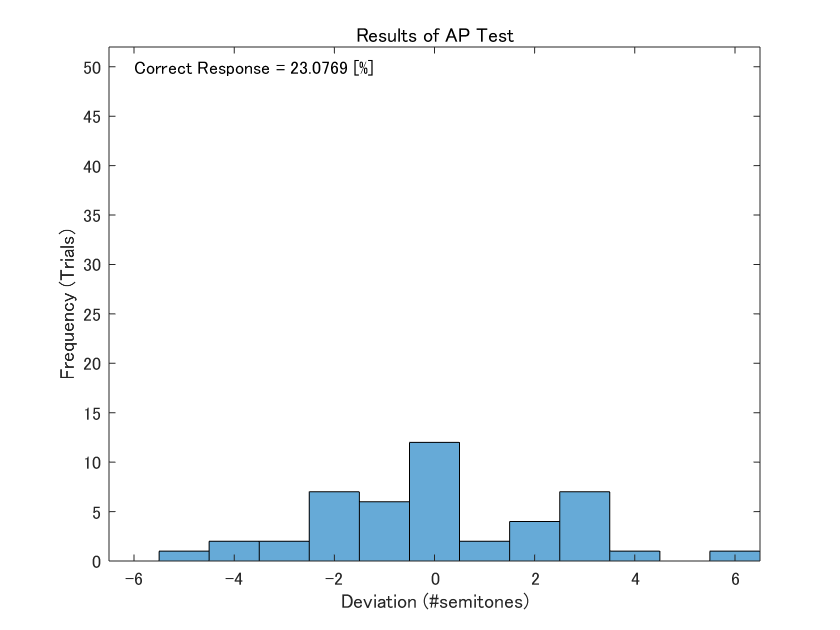


% ID
idstr = input('Your ID? ','s') ;

% Sound Settings
Fs = 48000 ; % Sampling Frequency
d = 0.5 ; % Tone duration in second
a = 1 ; % Tone amplitude (from 0.0 to 1.0)
rfd = 0.05 ; % Rise & fall duration in second
Fref = 440 ; % Reference Frequency
SemTs = (-3:+1:+9)' ; % Semitone 
StrTs = {'F#';'G';'G#';'A';'A#';'B';'C';'C#';'D';'D#';'E';'F';'F#'}; % String
NumTs = [7,8,9,10,11,12,1,2,3,4,5,6,7]' ; % Number of the Tones
% Number of repetition
nRepeat = 4 ;
% repeated Semitones to Use
repSemTs = repmat(SemTs,nRepeat,1) ;
repStrTs = repmat(StrTs,nRepeat,1) ; 
repNumTs = repmat(NumTs,nRepeat,1) ;
% number of trials
nTrial = length(repSemTs) ;
% randomize trial order
iRand = randperm(nTrial) ;
expSemTs = repSemTs(iRand) ;
expStrTs = repStrTs(iRand) ;
expNumTs = repNumTs(iRand) ;
% Create string arrays for instruction
Str1 = [' 1) C\n',...
       ' 2) C#,Db\n',...
       ' 3) D\n',...≥
       ' 4) D#,Eb\n',...
       ' 5) E\n',...
       ' 6) F\n',...
       ' 7) F#,Gb\n',...
       ' 8) G\n',...
       ' 9) G#,Ab\n',...
       '10) A \n',...
       '11) A#,Bb \n',...
       '12) B \n'] ;
Str2 = 'What pitch do you think this note is?\n';
Str3 = '(Press Enter to hear the tone again.)\n';

% loop for each trial
for i = 1:nTrial
    % current semitone
   semitone = expSemTs(i) ;
    % calculate frequency from the semitone
   f = calcS2F(Fref,semitone);
    % create current tone
   S = createTone(a,f,d,rfd,Fs) ;
    % play sound
    sound(S,Fs);
    % flag for correct keyboard response
    flg = 0 ;
    while flg == 0 % if non-correct response
        % display trial number
       anstr = input([Str1,'Trial ',num2str(i),'/',num2str(nTrial),'\n',Str2,Str3,' '],'s') ;
        % check input string
       if isnan(str2double(anstr)) == 0 &&...
          str2double(anstr) >= 1 &&...
          str2double(anstr) <= 12
          flg = 1 ;
       else
          flg = 0 ;
          sound(S,Fs) ;
        end
    end
    % create input answer array
    ansNumTs(i,1) = str2double(anstr) ;
end

% calculate deviation between the stimulus and answer
dNumTs = expNumTs - ansNumTs ;

% If deviation is larger than 7, modify the value
% For example: 
% 7 -> -5
% 8 -> -4
% 9 -> -3 
for i = 1:nTrial
   if dNumTs(i) >= 7
      dNumTs(i) = dNumTs(i) - 12 ;
   end
end
% calculate percent correct answer
pCorrect = length(find(dNumTs==0))/length(dNumTs) * 100 ;

% Plot Result
h = figure(1); 
histogram(dNumTs) ;
xlim([-6.5 6.5]);
ylim([0 nTrial]);
xlabel('Deviation (#semitones)');
ylabel('Frequency (Trials)');
title('Results of AP Test');
str = ['Correct Response = ',num2str(pCorrect),' [%]'];
text(-6,nTrial-2,str) ;

% Data Save
data = [expNumTs, ansNumTs, dNumTs] ;
save(idstr,'data');
print(idstr,'-dpng');

## 付録1. 純音作成関数

演習：周波数（f）、振幅（a）、時間長（d）、音の立ち上がり/立ち下がり時間（rfd）、サンプリング周波数（Fs）を入力引数（input）とし、サイン波（y）を出力とする関数ファイル

function yw = createTone(a,f,d,rfd,Fs)
    % 入力引数：
    % Fs サンプリング周波数
    % f 音波の周波数（Hz） 
    % a 音波の振幅
    % d 音波の長さ（秒）
    % rfd 音波の立ち上がり/立ち下がり時間の長さ（秒）
    
    % 0秒からd秒まで、1/Fsの刻み幅で時間軸を作成
    t = 0:1/Fs:d ; 
    % サイン波の作成
    y = a*sin(2*pi*f*t) ; 
    % データポイント数
    n = length(y); 
    % 窓関数の作成
    nw = round(Fs*rfd) ; % 立ち上がり窓のデータ数         
    rw = sin(linspace(0,pi/2,nw)) ; % 窓関数の立上り部の作成
    w  = [rw,ones(1,n-nw*2),fliplr(rw)] ; % 窓関数の作成
    yw  = y.*w ; % サイン波に窓関数をかける
    yw = yw(1:end-1) ; % 最後をカットしポイント数を調整
end


## 付録2. 平均律の周波数を出力する関数

基準音とセミトーンを入力し、平均律で計算された周波数を出力する function Mファイル

function Fout = calcS2F(Fref,semitone)
    Fout = 2^(semitone/12) * Fref ;
end